# **Econometrics 2 (Fall 2021)**

## **Jordan Holbrook**

## **Homework 3: Time Series - MA(1) **

Due Friday on Sept. 17, 2021.

This code estimates an MA(1) model using Maximum Likelihood. The model is:

                                                                $x_t = \beta_0 + u_t + \beta_1u_{t-1}$ ,

with $u_t \sim N(0,\sigma)$.

## Set the parameters.

There are 50 simulations with 300 observations per simulation. Set $\beta_0 = 0, \beta_1 = 0.5$ and $\sigma = 2$.

clc
clear

global x T MA x2

T = 300;                    % Number of time periods.
MA = 1;                                            % MA order.
beta0 = 0.5;                                       % Beta 0.
beta1 = 0.5;
beta2 = 0.5;   
sigma = 2;                                         % Standard deviation.

sim = 50;                   % Number of simulations.
results_mat = zeros(sim,3);                        % Results matrix.
results_mat2 = zeros(sim,4);  

## Maximum Likelihood Estimation.

In each simulation, generate draw the error terms, $U$, from the normal distribution and generate the data, $X$. Estimate the model using Maximum Likelihood and record the estimates.

for s = 1:sim
    
    u = normrnd(0,sigma,T,1);
    
    x = zeros(T,1);   
    x2 = zeros(T,1);
    x(1) = beta0 + u(1) + beta1*normrnd(0,sigma,1,1);
    x2(1) = beta0 + u(1) + beta1*normrnd(0,sigma,1,1);
    x2(2) = beta0 + u(2) + beta1*u(1) + beta2*normrnd(0,sigma,1,1);
        
    for j = 2:T            
        x(j) = beta0 + u(j) + beta1*u(j-1);
    end
    
    for j = 2:T-1
        x2(j+1) = beta0 + u(j+1) + beta1*u(j)+beta2*u(j-1); 
    end
        
    init = [0.5 0.5 0.5];

    options = optimset('Display','off'); 
    [b_mle,~,~,~,~,hess] = fminunc('logl_MA',init,options);
    
    
    init2 = [0.5 0.5 0.5 0.5];
    
    [b_mle2,~,~,~,~,hess2] = fminunc('logl_MA2',init2,options);
    
    results_mat(s,:) = b_mle';
    results_mat2(s,:) = b_mle2';
    
end


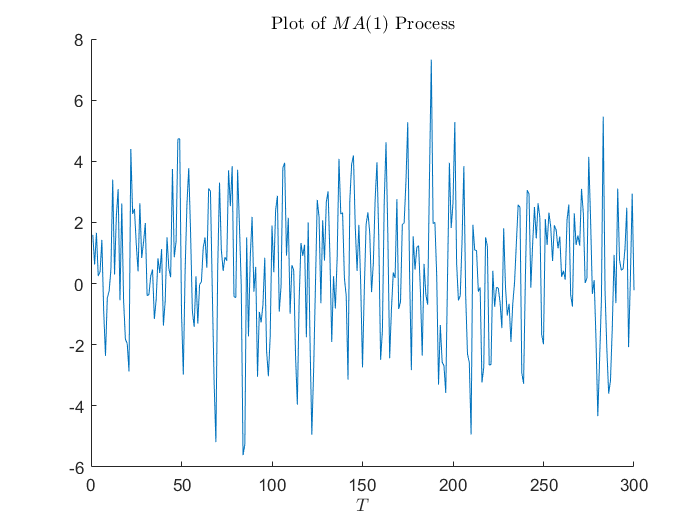

close all
figure(8)
hold on
plot(x)
xlabel('$T$','interpreter','LaTex'); 
title('Plot of $MA(1)$ Process','interpreter','LaTex')
hold off

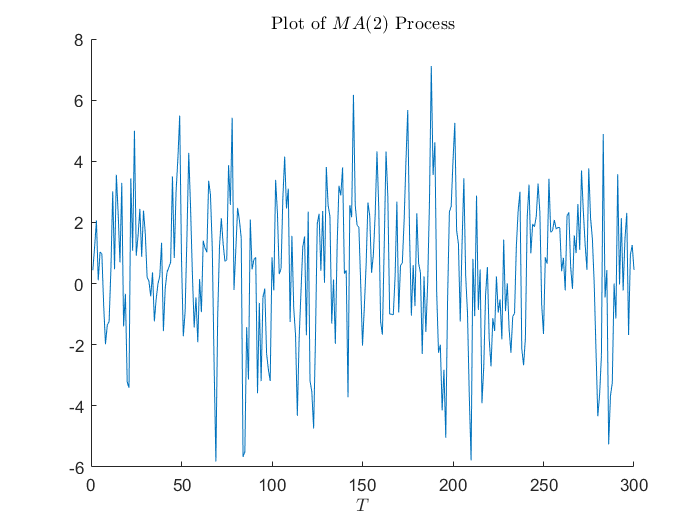

close all
figure(9)
hold on
plot(x2)
xlabel('$T$','interpreter','LaTex'); 
title('Plot of $MA(2)$ Process','interpreter','LaTex')
hold off

## Display the results of the last simulation.

The estimate and standard error (in parenthesis) of $\beta_0$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(1),sqrt(hess(1,1)))

 0.5082
(6.0712)


The estimate and standard error (in parenthesis) of $\beta_1$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(2),sqrt(hess(2,2)))

 0.4992
(18.8260)


The estimate and standard error (in parenthesis) of $\sigma$ in the last simulation is:

fprintf(' %0.4f\n(%0.4f)\n',b_mle(3),sqrt(hess(3,3)))

 1.9050
(12.8547)


## Empirical results.

The average and standard deviation (in parenthesis) of $\beta_0$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,1)), std(results_mat(:,1)))

 0.5258
(0.1649)


The average and standard deviation (in parenthesis) of $\beta_1$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,2)), std(results_mat(:,2)))

 0.5086
(0.0485)


The average and standard deviation (in parenthesis) of $\sigma
$ is:

fprintf(' %0.4f\n(%0.4f)\n', mean(results_mat(:,3)), std(results_mat(:,3)))

 2.0076
(0.0777)


## Plot the estimated coefficients from all simulations.

bins = 10;

Plot a histogram of $\beta_0$.

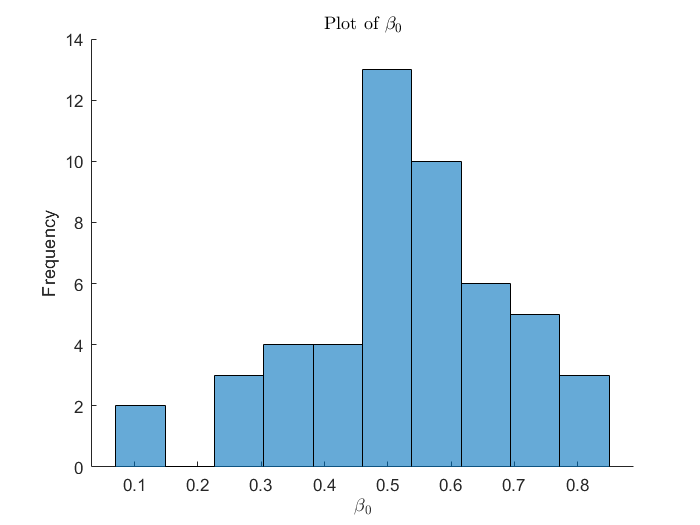

close all
figure(1)
hold on
histogram(results_mat(:,1),bins)
xlabel('$\beta_{0}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{0}$','interpreter','LaTex')
hold off

Plot a histogram of $\beta_1$.

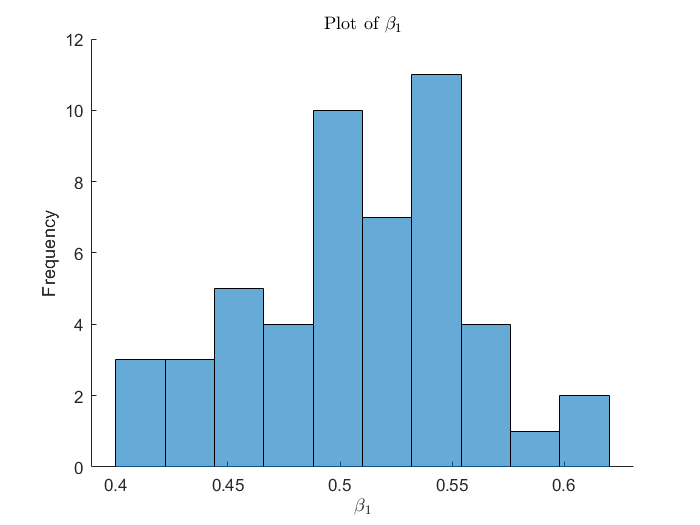

figure(2)
hold on
histogram(results_mat(:,2),bins)
xlabel('$\beta_{1}$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\beta_{1}$','interpreter','LaTex')
hold off

Plot a histogram of $\sigma$.

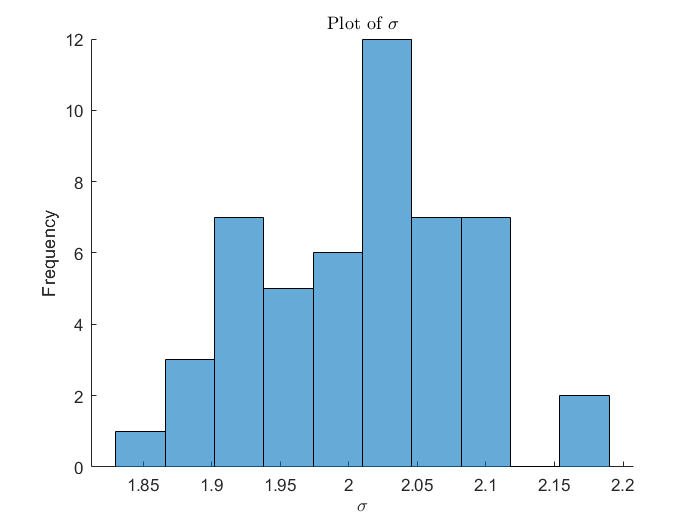

figure(3)
hold on
histogram(results_mat(:,3),bins)
xlabel('$\sigma$','interpreter','LaTex'); ylabel('Frequency')
title('Plot of $\sigma$','interpreter','LaTex')
hold off